# Chapter 00 - Using git with MATLAB.

Author: Louise Brown, [louise.brown@nottingham.ac.uk](http://louise.brown@nottingham.ac.uk) + material from Use Git in Matlab - [https://uk.mathworks.com/help/matlab/matlab_prog/use-git-in-matlab.html](https://uk.mathworks.com/help/matlab/matlab_prog/use-git-in-matlab.html) and [Software Carpentry Version Control with Git, Beginner lesson](https://swcarpentry.github.io/git-novice/index.html), made available under the [Creative Commons Attribution license](https://creativecommons.org/licenses/by/4.0/)

*Title Slide*

*Course outline slide*

*Intro to version control slides*

This chapter gives a brief introduction to using git version control with MATLAB and to cloning the course materials. You can use Git™ source control in MATLAB® to manage your  files and collaborate with others. Using Git, you can track changes to  your files and recall specific versions later. From the MATLAB Current Folder browser, you can clone an  existing remote repository, add files to the local repository, commit changes, and push and  pull changes to and from the remote repository. 

You can use a git repository to keep track of changes to your code with or without linking it to a remote repository. The figure below gives the basic workflow when working with just a local repository (on your own computer).

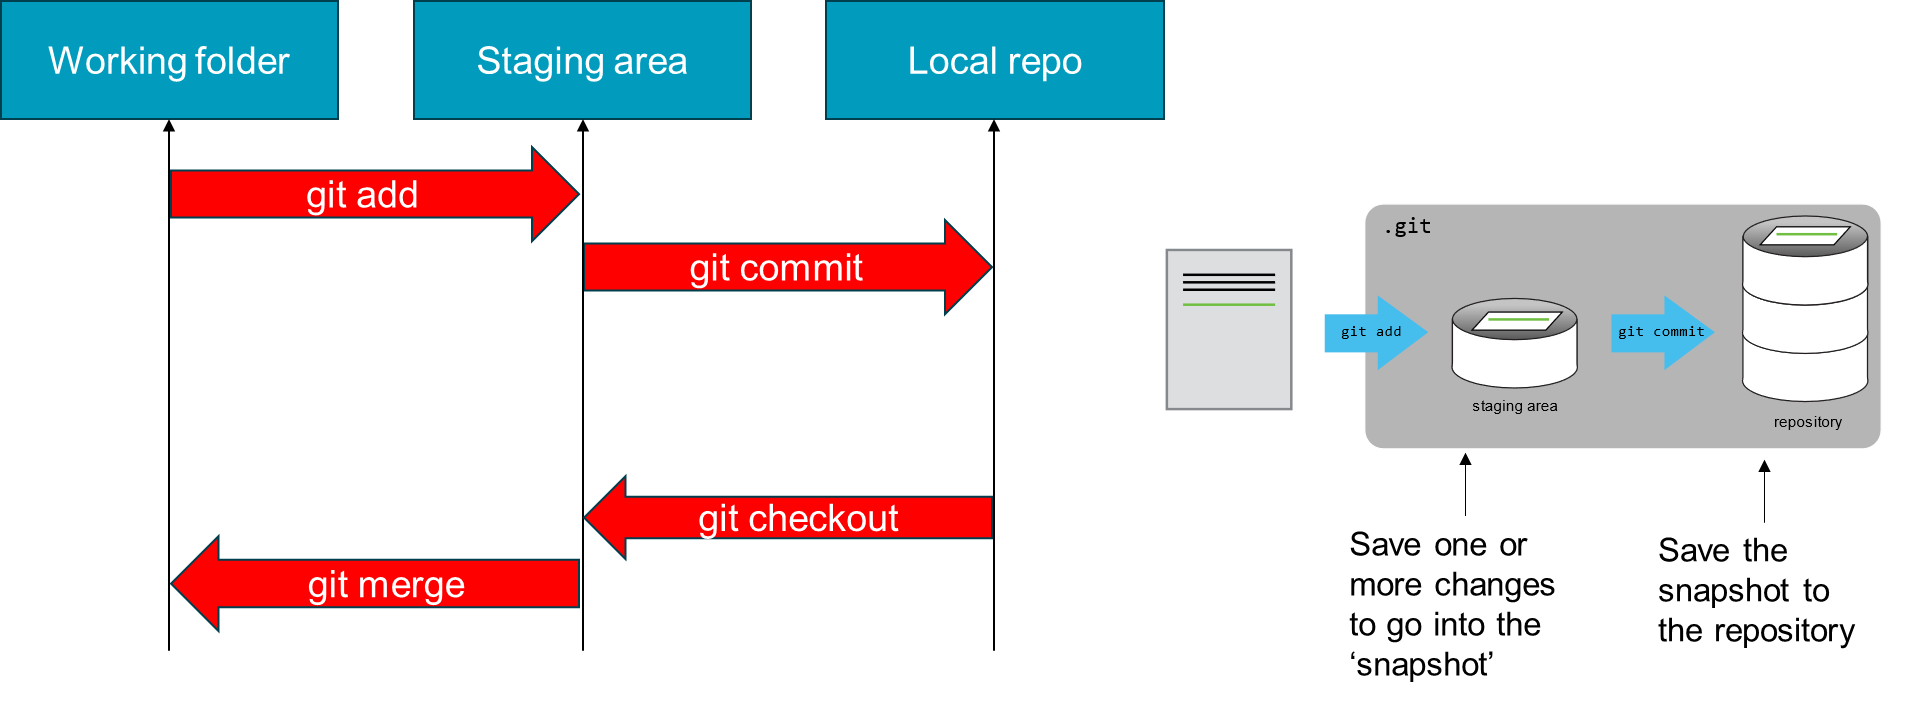

The next figure shows the workflow when combined with the use of a remote repository such as GitHub.

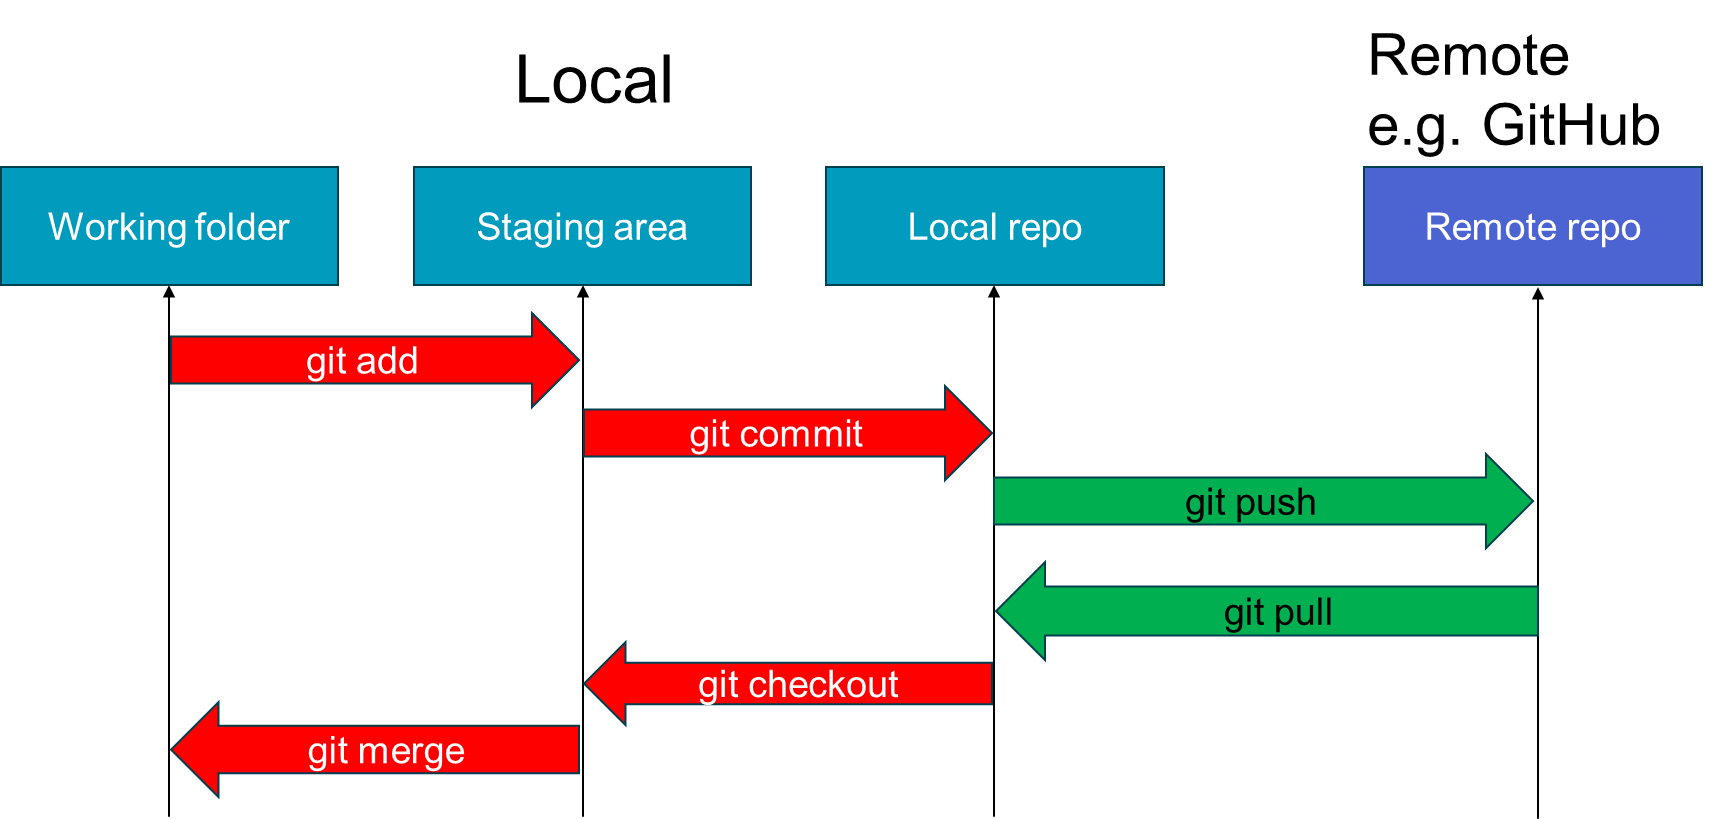

*Put that into context with how things work in practise:*

*Show Code folder with repos.*

*Show GitHub*

*Show TexGen*

## Create a Local Working Folder and link to a GitHub Repository

We will start by creating a new folder and link it to a new GitHub repository.

Create  a new folder. *Move to Code folder. Right click in Current Folder window and create new folder, MatlabGitDemo.*

We want to create a corresponding repository on GitHub. Open your GitHub account and from your Home page, select the **Repositories** tab.

Select the **New ** button shown below:

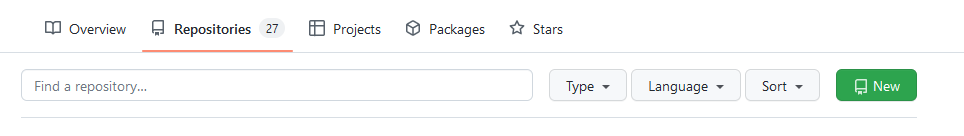

Enter a name for the repository in the box given. It does not have to be the same as the folder you created but it makes things clearer if you do. A public repository can be seen by anyone. A private repository can only be seen by you and any collaborators that you give permission to view. If you used your university email address to create your GitHub account then you should be able to create private repositories free of charge.

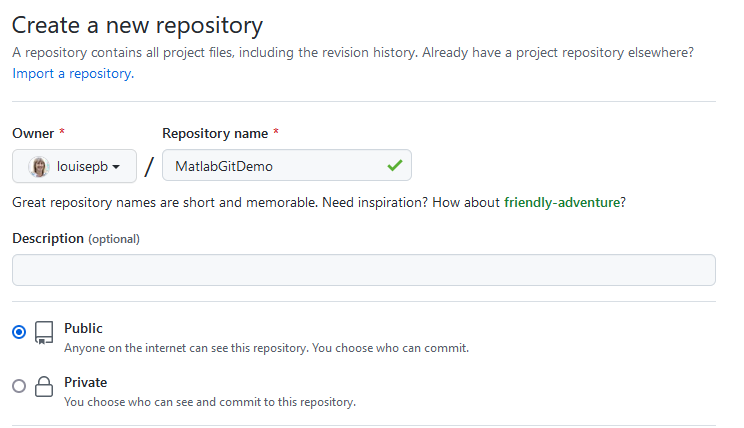

- Select the **Create repository ** button at the bottom of the page.

The repository will be created and a page displayed which gives various options for linking to code on your local machine. We will link to the folder we created earlier. Copy the link given in the Quick setup option: *If it doesn't show this use Code button for link.*

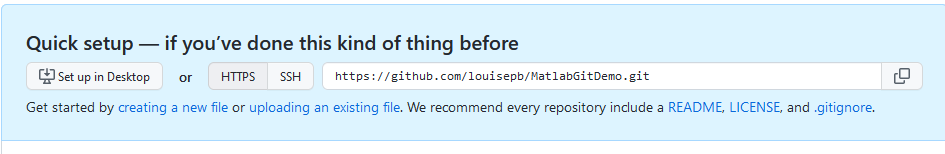

- Open the folder that you created earlier, right click in the white space and select **Source Control->Manage Files. **MATLAB opens the Manage Files Using Source Control dialog box. 

- Set the **Source control integration** option to `Git`.

- Paste the path that you copied from GitHub into the **Repository path ** field. You may need to use Ctrl-v for this.

- In the **Sandbox** field, enter the path of the working folder in which to store the retrieved files. 

- Click the **Retrieve** button. If prompted, enter the login information for the remote repository. 

A .git folder should appear in the working folder. This contains all of the information about the repository and is generated and updated automatically by git. **Do not edit anything in this folder!**

The local and remote repositories are now linked.

## Add Files to the Repository and Push to GitHub

Create a new script file, add some text and save.

The circle in the Current Folder window shows that there is a file which is not in the git repo. 

To add the file to source control, mark it for addition: right-click the file in the Current Folder browser and select **Source Control** > **Add to Git**. MATLAB indicates the file is marked for addition using the Added icon ().

To record and save the current state of new and modified files in your working folder, commit them to your local repository.

To commit files to your local repository:

- In the Current Folder browser, right-click and select **Source Control** > **View and Commit Changes**. The View and Commit Changes dialog box opens.

- Select the files to commit.

- Enter a comment in the **Comment** section.

- Click the **Commit** button.

The green circle shows that the changes to the file have been commited to the repo.

Make another change to the file and save. Note that the symbol changes from a green circle to a blue square, indicating that changes have been made to the file which haven't been saved to the repo.

To view changes which have been made to the file, right-click and select **Source Control -> Compare to Ancestor.**

Repeat the process for commiting the changes.

To view changes which have been made to the repo, right-click and select **Source Control -> Show Revisions.**

If you look at the repo in GitHub at this point you will see that there are still no files there. The changes in the local repo need to be pushed to the remote one using **Source Control -> Push. **If you refresh your GitHub page you should see the file in the repo.

*Show the Commits. Click on the #number to show changes.*

Some files used in MATLAB are binary files, such as .mlx, .mat, .fig etc. In order for git to process these correctly without corrupting them it is necessary to register them as binary files by creating a .gitattributes file. The simplest way to do this is to copy the following command into the MATLAB Command Window:

copyfile(fullfile(matlabroot,'toolbox','shared','cmlink','git','auxiliary_files', ...
    'mwgitattributes'),fullfile(pwd,'.gitattributes'))

*Show the .gitattributes file.*

## Forking the Course Materials from GitHub

A repository from another GitHub user can be copied in two ways, cloning and forking. Cloning will create a copy of the repository on your local machine. Forking a repository will create a copy of the repo in your GitHub account which you can then clone to your local machine. In this case you will then be able to make changes and push them to the version of the repo in your GitHub account.  

*Show forked git-consortium.*

To fork the course materials go to **louisepb** and select the **Further-MATLAB-Student-Materials **repository. Click the **Fork **button at the top right of the page:

The repository should appear in the list on your profile page. Click on the repository name and then use the green **Code **button to clone the repository:

Copy the repo link, right click in the Current Folder Window, select **Source Control->Manage Files **and complete the source control dialog as earlier, using the link just copied and a suitable folder name. If you select a folder which does not currently exist a dialog box will give the option to create the folder.

You are now up and running with source control and we can move onto some MATLAB!